# 遗传算法

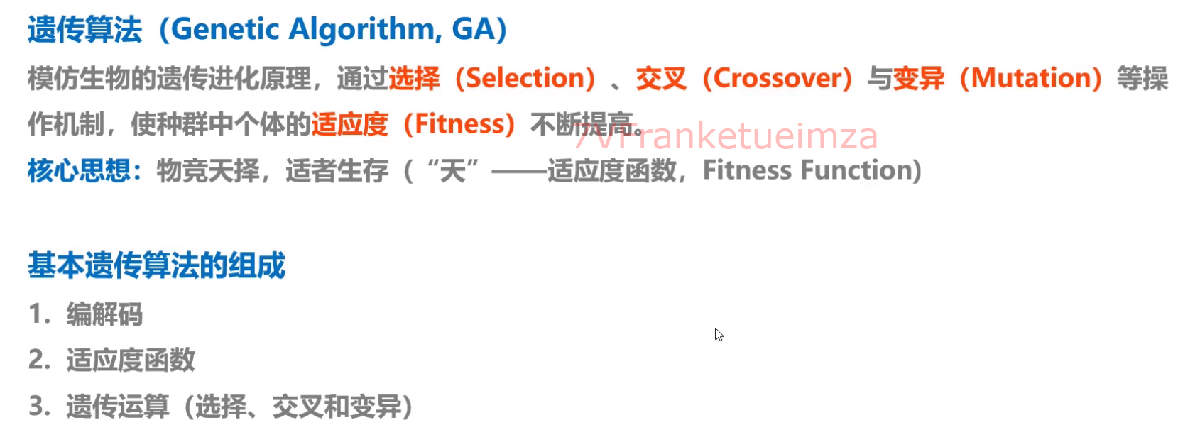

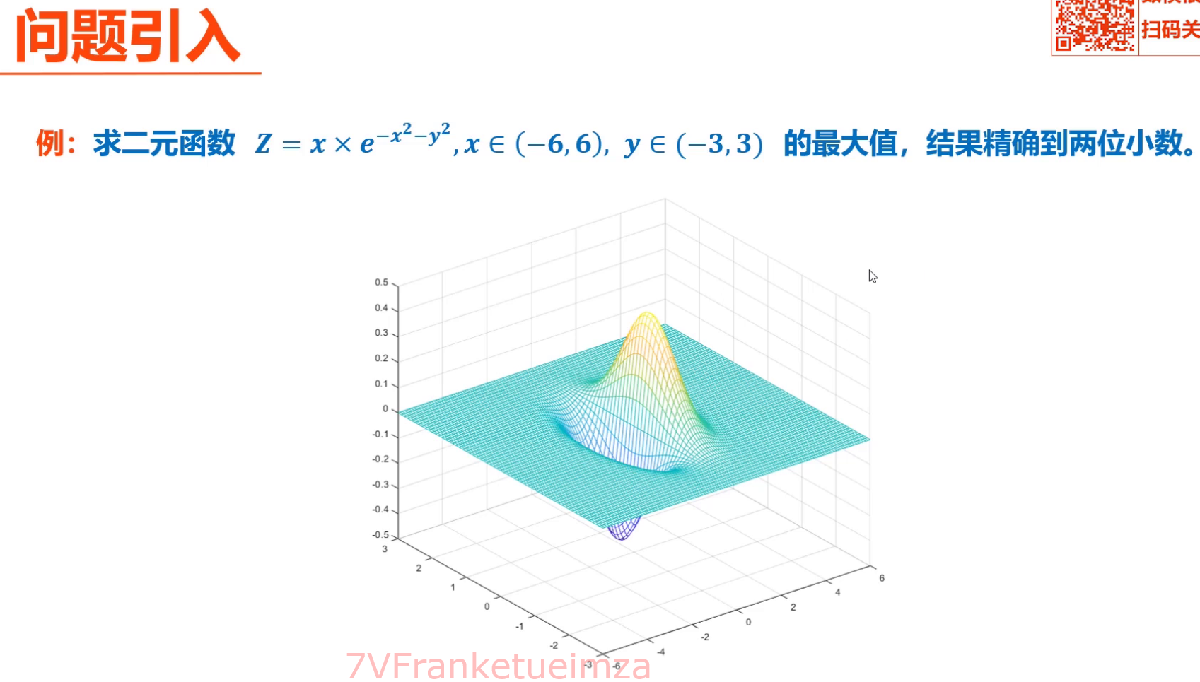

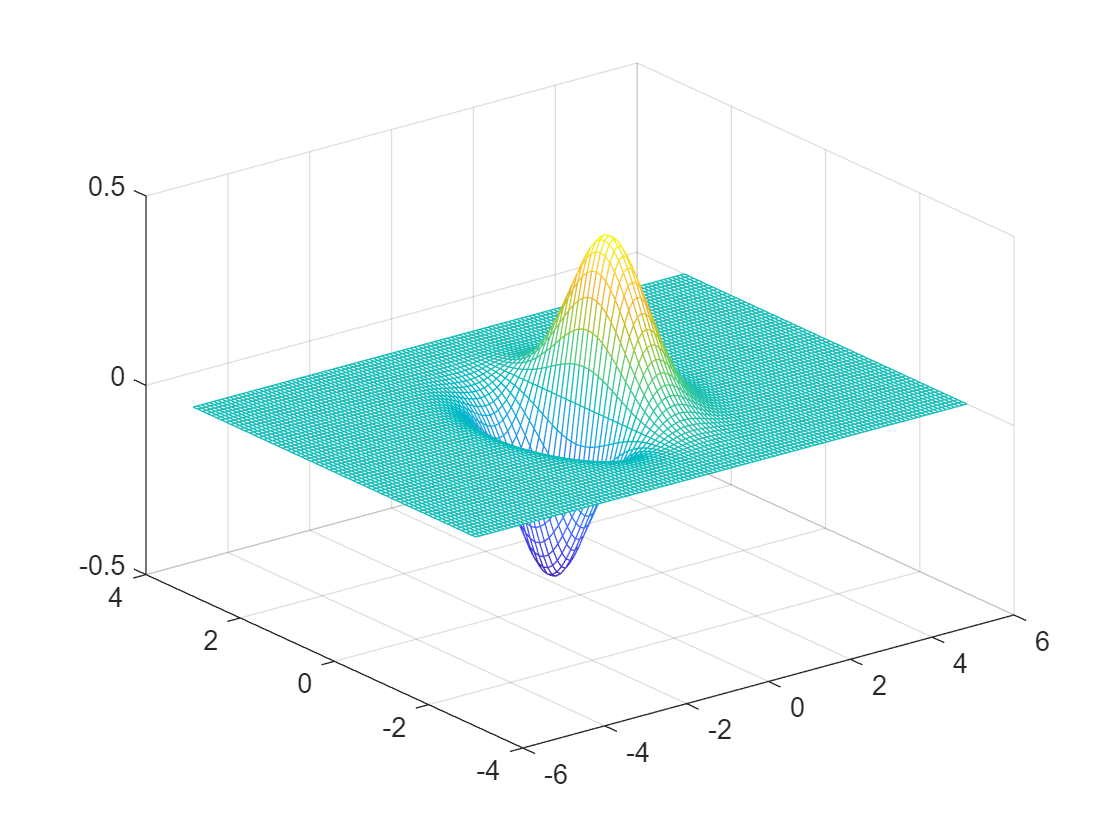

clc;clear;close all;
% 绘制图像
x = -6:0.1:6;
y = -3:0.1:3;
[X,Y] = meshgrid(x,y);
Z = X.*exp(-X.^2-Y.^2);
mesh(X,Y,Z);

% [x,fval] = ga(fun,nvars,A,b,Aeq,beq,lb,ub,nonlcon,IntCon)
% fun 函数句柄
% nvars 变量个数
% A 不等式约束系数矩阵
% b 不等式约束常量向量
% Aeq 等式约束系数矩阵
% beq 等式约束常量向量
% lb 变量上限
% ub 变量下限
% nonlcon 非线性约束
% IntCon 整数约束
fun = @(x)-x(1)*exp(-x(1)^2-x(2)^2);
nvars = 2;
lb = [-6,-3];
ub = [6,3];
[x,fval] = ga(fun,nvars,[],[],[],[],lb,ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     0.7071    0.0000


fval = -0.4289

fval = -fval; % 要取个反才行